clear; format long
simplify = @(exp) simplify(exp, 'IgnoreAnalyticConstraints',true, 'Steps',150);

e1rot = @(a) [1 0 0; 0 cos(a) -sin(a); 0 sin(a) cos(a)];
e2rot = @(a) [cos(a) 0 -sin(a); 0 1 0; sin(a) 0 cos(a)];
e3rot = @(a) [cos(a) -sin(a) 0; sin(a) cos(a) 0; 0 0 1];

s_pi = sym(pi);
N = 100;
D = 4; % Precision of resulting equations

# LFAST Primary Mirror Control

Author: Kevin Gilliam

Date: October 19, 2022

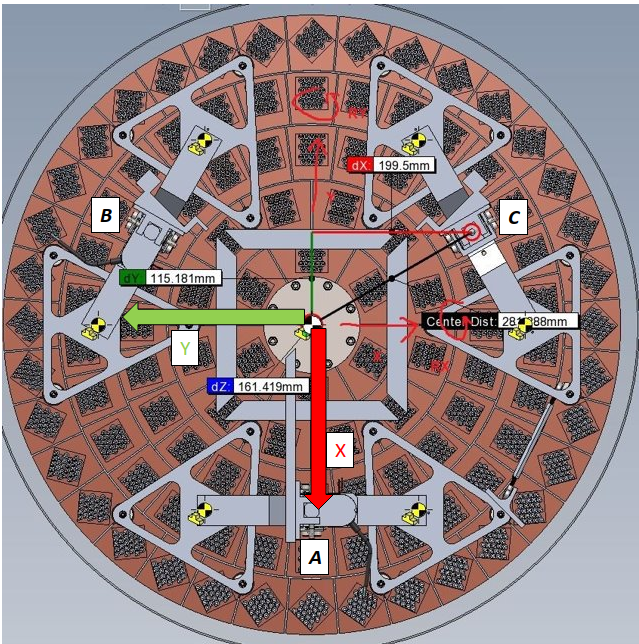

## Constants

arcsec_per_deg = 3600

arcsec_per_deg =         3600


deg_per_arcsec = 1/arcsec_per_deg

deg_per_arcsec =      2.777777777777778e-04


rad_per_deg = pi/180

rad_per_deg =    0.017453292519943


deg_per_rad = 1/rad_per_deg

deg_per_rad =   57.295779513082323


arcsec_per_rad = arcsec_per_deg * deg_per_rad

arcsec_per_rad =      2.062648062470964e+05


rad_per_arcsec = 1/arcsec_per_rad

rad_per_arcsec =      4.848136811095360e-06


mm_per_in = 25.4

mm_per_in =   25.399999999999999


### Geometry Constants

Radius of the motor positions in a circle (see above image)

r_motors_um = 281.288*1000;

## Purpose

The purpose of this analysis is to derive equations which relate tip and tilt commands for the primary mirror in to linear offsets to be applied by the three actuators underneath it. The tip and tilt transforms must not add piston/focus to the image reflected off the primary mirror.

## Analysis Approach

The analysis will be broken in to five steps:

- Define a fixed base frame, and determine the coordinates of the three motors in that frame.

- Determine a vector (the "tip/tilt vector") with the desired tip and tilt relative to the nominal optical axis of the system.

- Define a tip/tilt plane which intersects the "mirror vertex" (definition to follow), whose normal is the tip/tilt vector.

- Compute the distance of the three motors from tip/tilt plane, parallel to the optical axis.

- Add the piston constant to the resulting equations

## Step 1. The Fixed Base Frame

The base frame is fixed - all other frames are defined with respect to the base frame. 

The base frame is defined with basis vectors: $\left\lbrack \begin{array}{ccc}
e_1  & e_2  & e_3 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
1 & 0 & 0\\
0 & 1 & 0\\
0 & 0 & 1
\end{array}\right\rbrack$ 

e_basis = (eye(3));
e_1 = e_basis(:,1);
e_2 = e_basis(:,2);
e_3 = e_basis(:,3);

The coordinates of the three motors are defined relative to the fixed base frame. They are arranged in a circular pattern with radius 281.288mm. In polar coordinates:

R_Motors = sym(r_motors_um);
motorAp = [0, R_Motors];
motorBp = [sym(2/3)*s_pi, R_Motors];
motorCp = [sym(4/3)*s_pi, R_Motors];
% polarplot([motorAp(1) motorBp(1) motorCp(1)], [motorAp(2) motorBp(2) motorCp(2)], '*-');

For conveinence, they are located in the plane defined by $e_1$ and $e_2$.  In cartesian coordinates:

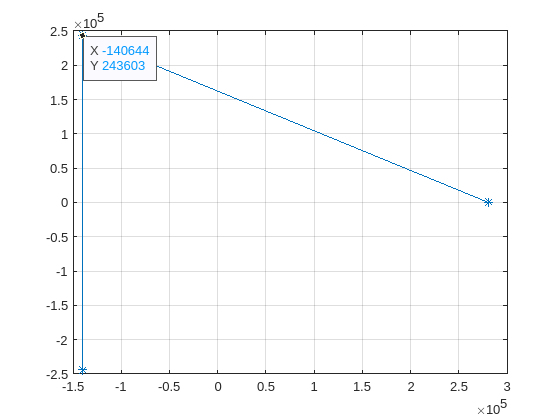

[mA_x, mA_y] = pol2cart(motorAp(1), motorAp(2)); motorA = [mA_x, mA_y, 0];
[mB_x, mB_y] = pol2cart(motorBp(1), motorBp(2)); motorB = [mB_x, mB_y, 0];
[mC_x, mC_y] = pol2cart(motorCp(1), motorCp(2)); motorC = [mC_x, mC_y, 0];

plot([mA_x mB_x mC_x], [mA_y mB_y mC_y], '*-'); grid on
ax = gca;
chart = ax.Children(1);
datatip(chart,-140.6,-243.6);
datatip(chart,281.3,0);
datatip(chart,-140.6,243.6);

## Step 2. The Tip/Tilt Vector

The tip/tilt vector is to be compared to the optical axis of the system, so both quantities need defining.

The nominal optical axis of the system is defined as the line which instersects the origin and coincides with $e_3$:

A_o = e_3;

Variables:

- $\alpha$: Tip angle (rotation around $e_1$)

- $\beta$: Tilt angle (rotation around $e_2$)

The tip/tilt vector is defined after applying the corresponding rotations to the optical axis:

syms alpha beta real
assumeAlso(alpha > -s_pi/4 & alpha < s_pi/4);
assumeAlso(beta > -s_pi/4 & beta < s_pi/4);
% assumptions(alpha)
% assumptions(beta)
V_tt = (e2rot(alpha) * e1rot(beta)  * A_o)

$$V\_tt = \left(\begin{array}{c} -\cos\left(\beta \right)\,\sin\left(\alpha \right)\\ -\sin\left(\beta \right)\\ \cos\left(\alpha \right)\,\cos\left(\beta \right) \end{array}\right)$$

## Step 3. The Tip/Tilt Plane

The Primary Mirror is spherical, and as such does not technically have a vertex. For this analysis that doesn't matter, so the mirror vertex is just defined as the point where the nominal optical axis intersects the surface of the mirror when no tip or tilt is applied. This is equivalent to modeling the primary mirror as a flat circle, whose center intersects $e_3$. The scalar equation for the plane containing that circle is:

syms p [1 3]
TipTiltPlane = (V_tt(1)*(-p(1)) + V_tt(2)*(-p(2)) + V_tt(3)*(-p(3)) == 0)

$$TipTiltPlane = p_{2}\,\sin\left(\beta \right)-p_{3}\,\cos\left(\alpha \right)\,\cos\left(\beta \right)+p_{1}\,\cos\left(\beta \right)\,\sin\left(\alpha \right)=0$$

Note that the distance of the vertex from the Base Plane (defined in Step 1) is piston/focus, which is being neglected in this part of the analysis. It is trivial to add piston after calculating the motor offsets for tip and tilt, so for now it is assumed that the vertex coincides with the origin. The equation of the tip/tilt plane which intersects the origin is simply:

TipTiltPlaneDistance = solve(TipTiltPlane, p(3))

$$TipTiltPlaneDistance = \frac{p_{2}\,\sin\left(\beta \right)+p_{1}\,\cos\left(\beta \right)\,\sin\left(\alpha \right)}{\cos\left(\alpha \right)\,\cos\left(\beta \right)}$$

#### Test Tip/Tilt Plane

TipTiltPlaneDistanceFn = matlabFunction(TipTiltPlaneDistance)

TipTiltPlaneDistanceFn = function_handle with value:
    @(alpha,beta,p1,p2)(p2.*sin(beta)+p1.*cos(beta).*sin(alpha))./(cos(alpha).*cos(beta))


## Step 4. Calculate the distance

To calculate the distance from the three motors to the tip/tilt plane, just plug in the $e_1$and $e_2$ coordinates for each motor:

digits(D); % Reducing precision for printing in a readable format
MotorADistance = vpa(simplify(subs(...
    TipTiltPlaneDistance, [p(1), p(2)], [motorA(1), motorA(2)])))

$$MotorADistance = 2.813e+5\,\tan\left(\alpha \right)$$

MotorBDistance = vpa(simplify(subs(...
    TipTiltPlaneDistance, [p(1), p(2)], [motorB(1), motorB(2)])))

$$MotorBDistance = \frac{2.436e+5\,\tan\left(\beta \right)}{\cos\left(\alpha \right)}-1.406e+5\,\tan\left(\alpha \right)$$

MotorCDistance = vpa(simplify( ...
    subs(TipTiltPlaneDistance, [p(1), p(2)], [motorC(1), motorC(2)])))

$$MotorCDistance = -1.406e+5\,\tan\left(\alpha \right)-\frac{2.436e+5\,\tan\left(\beta \right)}{\cos\left(\alpha \right)}$$

## Step 5. Add Piston

Define $\gamma \;$as the piston value. The resulting expressions for the three motors which includes tip, tilt and piston becomes:

syms gamma
MotorADistance = MotorADistance+gamma

$$MotorADistance = \gamma +2.813e+5\,\tan\left(\alpha \right)$$

MotorBDistance = MotorBDistance+gamma

$$MotorBDistance = \gamma -1.406e+5\,\tan\left(\alpha \right)+\frac{2.436e+5\,\tan\left(\beta \right)}{\cos\left(\alpha \right)}$$

MotorCDistance = MotorCDistance+gamma

$$MotorCDistance = \gamma -1.406e+5\,\tan\left(\alpha \right)-\frac{2.436e+5\,\tan\left(\beta \right)}{\cos\left(\alpha \right)}$$

## Conversions

#### Step sizes to angular and linear travel

- Part# 23K2120A4-50SMSN-070

- Fourteen (14) x   Nema 23 Kaptive Linear Actuator, 2-Phase, 1.8 Degrees Step Angle, Single Stack 

- 2A/Phase, A Lead (0.635mm/rev), Qty 4 Flying Lead Wires (Bipolar). Wire Length = 320mm

- Stroke Length = 0.5inches, Standard Greased Screw, Metric End Machining, Standard Nut

- [https://dingsmotionusa.com/nema-23-linear-actuators](https://dingsmotionusa.com/nema-23-linear-actuators)

microstep_ratio = 16; %adjusted by moving the jumpers around on the CNC shield
deg_per_step = 1.8/microstep_ratio; % Per motor specs
steps_per_deg = 1/deg_per_step;
% stepsPerRev = 200; % [1 step]/[1.8 deg] * [360 deg] / [1 rev] = [200 steps per rev]
% microStepPerRev = stepsPerRev * 16
mm_per_rev = 0.635; % Per motor specs
mm_per_deg = mm_per_rev/360;
mm_per_step =  mm_per_deg * deg_per_step; 
umPerStep = mm_per_step * 1000

umPerStep =    0.198437500000000


#### Range of motion conversions

full_stroke_in = 0.5; % Per motor spec
full_stroke_mm = mm_per_in*full_stroke_in;
full_stroke_um = full_stroke_mm*1000;
full_stroke_steps = full_stroke_um / umPerStep

full_stroke_steps =        64000


#### Angular deviation per step

rad_per_step = atan2(umPerStep, r_motors_um)

rad_per_step =      7.054602400385622e-07


arcsec_per_step = rad_per_step * arcsec_per_rad

arcsec_per_step =    0.145511619726584


mas_per_step = arcsec_per_step * 1000

mas_per_step =      1.455116197265841e+02


## Limits

Maximum travel required for focus is $\pm$1mm

focus_max_um = 1000;

...so the available stroke (in one direction) for tip/tilt motions is

non_focus_stroke_range_um = full_stroke_um/2-focus_max_um

non_focus_stroke_range_um =         5350


so the maximum angular deviation is...

max_angle_rad = atan2(non_focus_stroke_range_um, r_motors_um)

max_angle_rad =    0.019017359518293


max_angle_mas = arcsec_per_rad * max_angle_rad * 1000

max_angle_mas =      3.922611976372085e+06


max_angle_deg = max_angle_mas / 1000 / 3600

max_angle_deg =    1.089614437881135


## Inverse Equations

For figuring out tip/tilt/focus from motor positions.

syms zA zB zC real
assumeAlso(zA >= 0)
assumeAlso(zB >= 0)
assumeAlso(zC >= 0)

motorA_coords = [mA_x mA_y zA];
motorB_coords = [mB_x mB_y zB];
motorC_coords = [mC_x mC_y zC];
AB = motorB_coords - motorA_coords;
AC = motorC_coords - motorA_coords;
normalVector = simplify(cross(AB, AC)')

$$normalVector = \left(\begin{array}{c} 140644\,\sqrt{3}\,\left(\mathrm{zB}-2\,\mathrm{zA}+\mathrm{zC}\right)\\ 421932\,\mathrm{zC}-421932\,\mathrm{zB}\\ 118684408416\,\sqrt{3} \end{array}\right)$$

normalVector = vpa(normalVector, 16);
normalVector = normalVector./normalVector(3)

$$normalVector = \left(\begin{array}{c} 1.185e-6\,\mathrm{zB}-2.37e-6\,\mathrm{zA}+1.185e-6\,\mathrm{zC}\\ 2.053e-6\,\mathrm{zC}-2.053e-6\,\mathrm{zB}\\ 1.0 \end{array}\right)$$

### For checking the math:

zA_fn = matlabFunction(MotorADistance);
zB_fn = matlabFunction(MotorBDistance);
zC_fn = matlabFunction(MotorCDistance);
normalVectorFn = matlabFunction(normalVector)

normalVectorFn = function_handle with value:
    @(zA,zB,zC)[zA.*-2.370050150260483e-6+zB.*1.185025075130242e-6+zC.*1.185025075130242e-6;zB.*-2.052523638364223e-6+zC.*2.052523638364223e-6;1.0]


## Plotter For Testing:

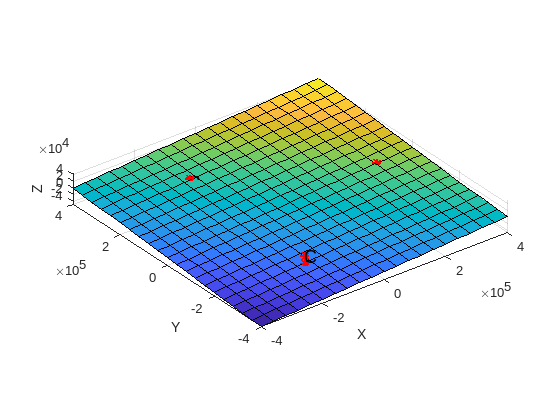

x = [-400:40:400]*1000;
y = x;
[X,Y] = meshgrid(x,y);

tip =3.4;
tilt = 3.4;
focus = 5;

tiltAngle = pi/180 * tilt;
tipAngle = pi/180 * tip;

gamma = focus;
zA = zA_fn(tipAngle, gamma);
zB = zB_fn(tipAngle, tiltAngle, gamma);
zC = zC_fn(tipAngle, tiltAngle, gamma);
% zA = 12.7;
% zB = -12.7;
% zC = -12.7;
Z = (TipTiltPlaneDistanceFn(tipAngle, tiltAngle, X, Y)+gamma);

n_hat = normalVectorFn(zA, zB, zC);
n_hat = n_hat./norm(n_hat);
surf(X, Y, Z); grid on; hold on;
line([mA_x mA_x], [mA_y mA_y], [0 zA], 'Color', 'red', 'LineStyle', '-')
line([mB_x mB_x], [mB_y mB_y], [0 zB], 'Color', 'red', 'LineStyle', '-')
line([mC_x mC_x], [mC_y mC_y], [0 zC], 'Color', 'red', 'LineStyle', '-')
plot3([mA_x mB_x mC_x], [mA_y mB_y mC_y], [0 0 0], 'r*','LineWidth',2);
plot3([mA_x mB_x mC_x], [mA_y mB_y mC_y], [zA zB zC], 'r*','LineWidth',2);
text(mA_x, mA_y, 0, 'A','FontSize', 14)
text(mB_x, mB_y, 0, 'B','FontSize', 14)
text(mC_x, mC_y, 0, 'C','FontSize', 14)
% plot3(0, 0 ,  gamma, 'bo')
% n_hat_scaled = n_hat;
% q = quiver3(0, 0, gamma, n_hat_scaled(1), n_hat_scaled(2), n_hat_scaled(3), 1, 'k', 'LineWidth',2);
q = quiver3(0, 0, gamma, n_hat(1), n_hat(2), n_hat(3), 100, 'k', 'LineWidth',2);
q.ShowArrowHead = "on";
q.AutoScale = "on";
q.MaxHeadSize = 80;
axis equal
hold off
xlabel('X')
ylabel('Y')
zlabel('Z')

% axis vis3d
% view([23 6])
norm_XZ = n_hat;
norm_XZ(2) = 0;
norm_XZ = norm_XZ / norm(norm_XZ);
tipAngleCalculated = acos(norm_XZ(3));
tipAngleCalculated * 180/pi

ans =    3.399999999998988


tiltAngleCalculated = acos(n_hat(3)*cos(tipAngleCalculated) ...
                        - n_hat(1)*sin(tipAngleCalculated) );
tiltAngleCalculated * 180/pi

ans =    3.399999999989978
